# Lecture 6 Diffraction-Limited Imaging

## 1. Diffraction-limited coherent imaging

### 1.1 Introduction

In this lecture, we will introduce a more accurate image formation physics model: scalar wave model. At focus, geometric optics predicts an infinitesimal focal point, leading to unbounded power density, which is not realistic for modeling the field distribution (ILL. 1.1). Realistically, if the scalar wave on a plane has finite support, the angular distribution of the field is not localized; in other words, light diffracts. Scalar wave diffraction theory can explain the phenomena of the distribution of the light intesnity focus.  

We will discuss both coherent imaging and incoherent imaging: For coherent systems, $f\left(x,y\right)$ represents complex amplitudes of the wave: electromagnetic fields or acoustic pressure or velocity. For incoherent systems (incoherent light source), $f\left(x,y\right)$ represents intensity.

            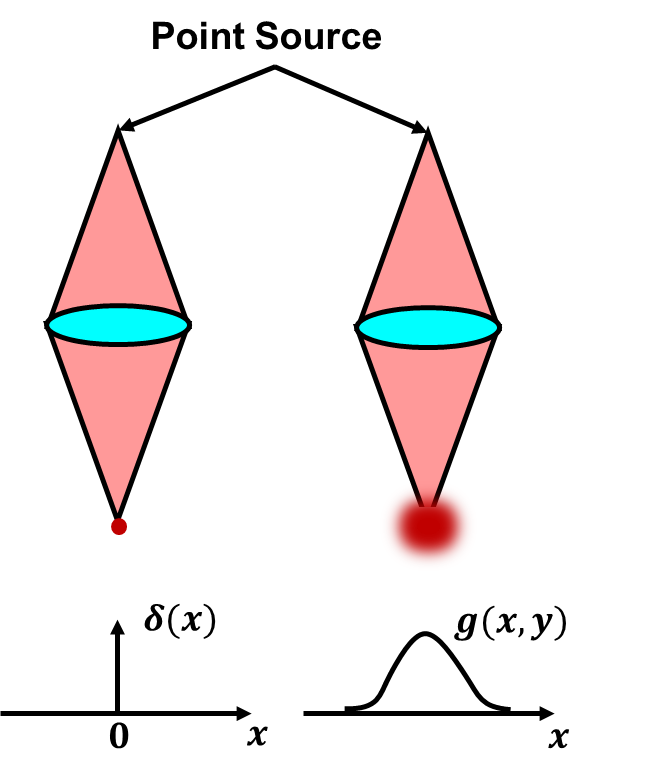

**ILL. 1.1 ***Geometric ideal focus vs focus point spread function(PSF) predicted by diffraction*

### 1.2 Scalar diffraction

#### 1.2.1 Fourier expansion of an optical wave

A monochromatic optical wave can be expanded as a sum of plane waves. Each plane wave has the form

$A\;\exp \left\lbrack j\left(k_x x+k_y y+k_z z\right)\right\rbrack$,

where $A$ is the field amplitude, and $\left(k_x ,k_u ,k_z \right)$ are components of the wavevector, which satisfy


$$k_x^2 +k_y^2 +k_z^2 =k^2$$



$$k=\frac{2\pi }{\lambda }$$


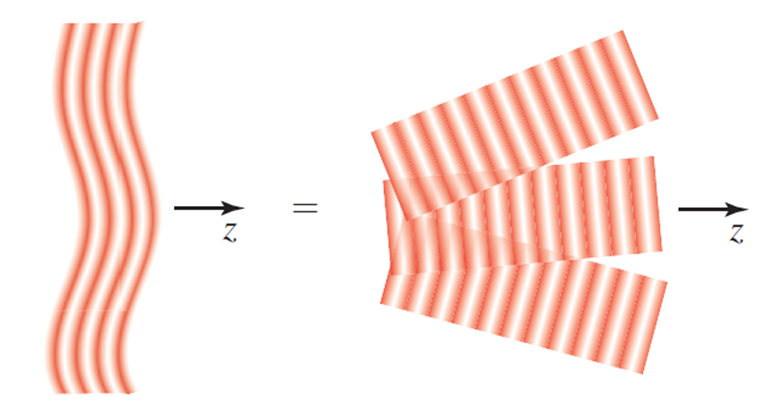

**ILL. 1.2 ***Expansion of optical wavefront *

The wave function $U\left(x,y,z\;\right)=A\;\exp \left\lbrack j\left(k_x x+k_y y+k_z z\right)\right\rbrack$ of a plane wave at points in the plane z=0 is a harmonic function: $f\left(x,y\right)=a\;\exp \left\lbrack -j\left(k_x x+k_y y\right)\right\rbrack$ with spatial frequencies $k_x$ and $k_y$.

For a 1D harmonic function:

$f\left(x,y\right)=\exp \left\lbrack j\left(\frac{2\pi }{\Lambda_x }x\right)\right\rbrack$,

where $\Lambda_x$ is the period of the harmonic function, the plane wave is diffracted to direction


$$\mathbf{k}=k_x \mathbf{i}+k_y \mathbf{j}+k_z \mathbf{k}$$


At the $z=0$ plane, the period matches $k_x =\frac{2\pi }{\Lambda_x }$. 

Therefore the sine of the diffracted plane wave direction $\theta_x$ is:


$$\sin {\;\theta }_x =\frac{k_x }{k}=\frac{\lambda }{\Lambda_x }$$


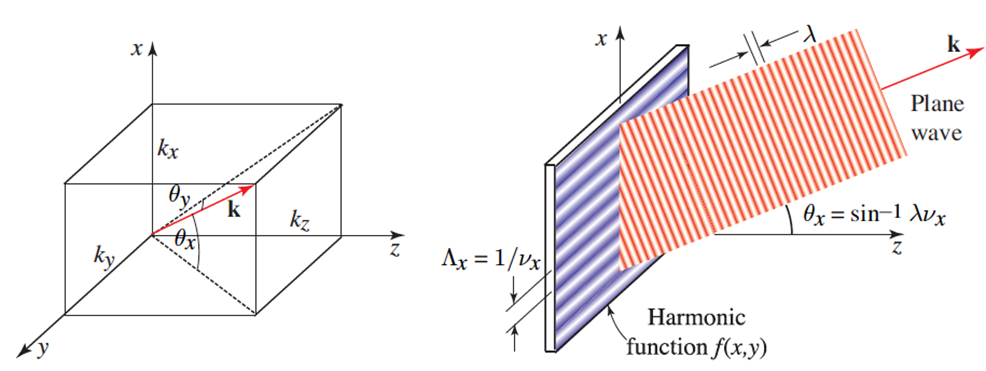

**ILL. 1.3 ***Diffracted plane wave of spatial harmonic function*

***Example 1.1***

Diffraction of a harmonic function.

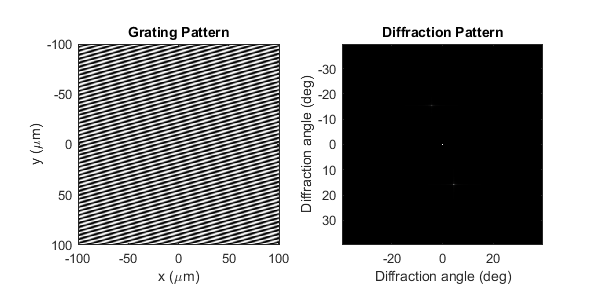

n = 256;
x=linspace(-100,100, n); %[unit: um]
y=linspace(-100,100, n);
lam_x = 4; % period in x direction [unit: um]
lam_y = 14; % period in y direction
lambda = 1; % wavelength [unit: um]
[X,Y]=ndgrid(x,y);
f=1+cos(2*pi./lam_x.*X+2*pi./lam_y.*Y);
dx = x(2)-x(1);
k=pi/dx*linspace(-1,1,n);
k_0 = 2*pi./lambda;
theta = asin(k./k_0)./pi*180; %diffraction direction [unit: degree]

figure()
subplot(121)
imagesc(x,x,f) % [unit: um]
axis image
colormap gray
title('Grating Pattern')
xlabel('x (\mum)')
ylabel('y (\mum)')
F=fftshift(fft2(fftshift(f)));

subplot(122)
imagesc(theta,theta, abs(F))
axis image
colormap gray
title('Diffraction Pattern')
xlabel('Diffraction angle (deg)')
ylabel('Diffraction angle (deg)')
set(gcf,'Position', [100 100 600 300])

* Please open the plot in seperate figure window to clearly spot the diffraction peak in the Diffraction Pattern.

#### **1.2.2 Phase shifting of a plane wave**

In Lecture 3, we learned that a 2D pattern, $f_0 \left(x,y\right)$, can be decomposed as a linear combination of harmonic functions. i.e,


$$f_0 \left(x,y\right)=\int_{-\infty }^{\infty } F\left(k_x ,k_y \right)\;\exp \left\lbrack j\left(k_x x_{k_y } y\right)\right\rbrack {\textrm{dk}}_x {\textrm{dk}}_y$$


The coefficient $F\left(k_{x,} k_y \right)\;$can be calculated through Fourier transform:


$$F\left(k_x ,k_y \right)=\int_{-\infty }^{\infty } f_0 \left(x,y\right)\exp \left\lbrack -j\left(k_x x+k_y y\right)\right\rbrack \textrm{dxdy}$$


Here the coefficents are complex valued, the amplitude represents the intensity that will be diffracted to a particular direction, and the phase represents the delay in that direction.

From superposition properties of a linear system, each wave vector propogates independently from the plane $z=0$ to a distance $z=d$, the wave is the superposition of the propagated diffracted plane waves.

If the propagation operator of a plane wave is  $P\left\lbrace \cdot \right\rbrace$, the pattern at $z=d$, $f_d \left(x,y\right)$ is


$$f_d \left(x,y\right)=\int_{-\infty }^{\infty } F\left(k_x ,k_y \right)P\left\lbrace \exp \left\lbrack j\left(k_x x+k_y y\right)\right\rbrack \right\rbrace \;{\textrm{dk}}_x {\textrm{dk}}_y \;$$


The wave function of a plane wave at points in the plane $z=d$ is also a harmonic funcrion with spatial frequencies $k_x$ and $k_y$ but it is phase shifted. 


$$\exp \left\lbrack j\left(k_x x+k_y y+k_z z\right)\right\rbrack =\left\lbrace \begin{array}{ll}
\exp \left\lbrack j\left(k_x x+k_y y\right)\right\rbrack  & z=0\\
\exp \left\lbrack {\textrm{jk}}_z d\right\rbrack \cdot \exp \left\lbrack j\left(k_x x+k_y y\right)\right\rbrack  & z=d
\end{array}\right.$$


Therefore, the propagation operator can be expressed as


$$\begin{array}{l}
P\left\lbrace \exp \left\lbrack j\left(k_x x+k_y y\right)\right\rbrack \right\rbrace \\
=\exp \left\lbrack j\sqrt{k^2 -k_x^2 -k_y^2 }d\right\rbrack \cdot \exp \left\lbrack j\left(k_x x+k_y y\right)\right\rbrack 
\end{array}$$


Here we used the relation $k_z =+\sqrt{\left(k^2 -k_x^2 -k_y^2 \right)}$ for a forward propagating wave. When we use the paraxial approximation, i.e., $k_x ,k_y <<k$, then 


$$k_z \approx k\left(1-\frac{1}{2}\left(\frac{k_x^2 }{k^2 }+\frac{k_y^2 }{k^2 }\right)\right)$$


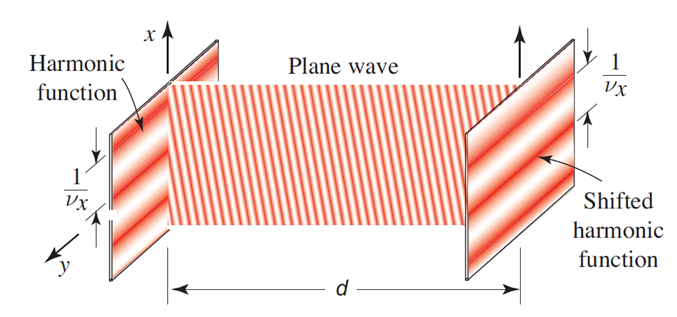

**ILL. 1.4 ***Phase shift of diffracted plane wave*

***Example 1.2***

Diffraction of a Gaussian beam

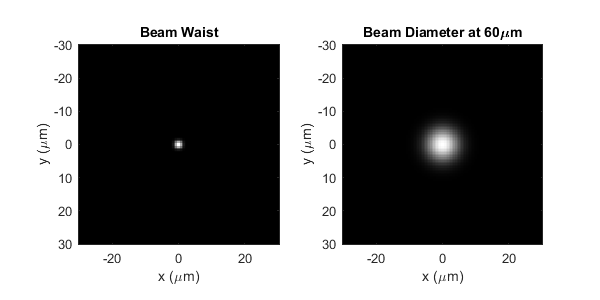

% unit in um
lambda=0.5;% the wavelength
% length on the x, y dimension 
lx=30;
ly=30;
% pixels on the x, y dimension
nx=128;
ny=128;
nz=10;
x=linspace(-lx,ly,nx);
y=linspace(-lx,ly,ny);
[X,Y]=ndgrid(x,y);

k=2*pi/lambda;
kx=2*pi/(x(end)-x(1))*((-nx/2):(nx/2-1));
ky=2*pi/(y(end)-y(1))*((-ny/2):(ny/2-1));
[Kx,Ky]=ndgrid(kx,ky);

% Diffraction of a gaussian beam
w=1.5; %waist size
E0=1e3*exp(-(X.^2+Y.^2)./w.^2);
E0_hat=fftshift(fft2(fftshift(E0)));
% now propagate the beam to a distance, z um
z=60;
figure()
subplot(121)
imagesc(x,x,abs(E0).^2)
title('Beam Waist')
xlabel('x (\mum)')
ylabel('y (\mum)')
axis image
colormap gray
% paraxial approximation
E_z_hat=E0_hat.*exp(1i.*k*(1-1/2*(Kx/k).^2-1/2*(Ky/k).^2).*z);
E_z=fftshift(ifft2(fftshift(E_z_hat)));
I_z=abs(E_z).^2;

subplot(122)
imagesc(x,x,I_z)
title(['Beam Diameter at ', num2str(z), '\mum'])
xlabel('x (\mum)')
ylabel('y (\mum)')
axis image
set(gcf,'Position', [100 100 600 300])

#### 1.3.1 PSF of an ideal lens with circular aperture

Ideal lens brings a plane wave with direction $\theta_x$ to its focus at location


$$x=\theta_x f=\frac{k_x }{2\pi }\lambda f$$


on the back focal plane, where f is the focal length of the lens.

As mentioned in Section 1.2, the angular spectrum of the diffracted field $F\left(k_x ,k_y \right)$ is the Fourier transform of the spatial distribution of the scalar field.


$$f\left(x,y\right)\overset{F\ldotp T}{\to} F\left(k_x ,k_y \right)$$


Replacing the direction $k_x ,k_y$ with the image plane coordinates, we get the image plane field $g\left(x,y\right)$


$$g\left(x,y\right)\proptoF\left(\frac{2\pi }{\lambda f}x,\frac{2\pi }{\lambda f}y\right)$$


The wave in the focal plane is proportional to a scaled version of the Fourier transform of the original wave.

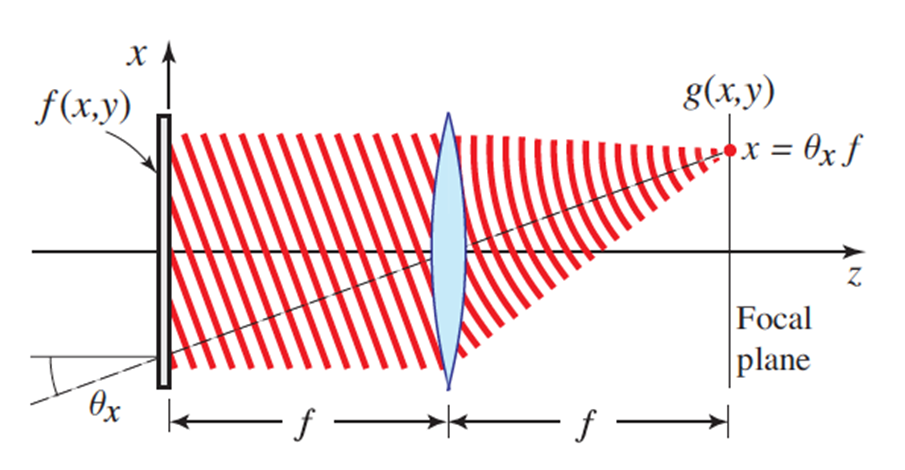

**ILL. 1.5 ***Fourier transform property of the lens*

In addition to magnification, which is explained by ray optics, the wave nature of light creates blur, even if the system is perfectly focused. For a lens with a circular aperture, the PSF of this blur is


$$h\left(x,y\right)\propto\frac{2J_1 \left(\pi \rho /\rho_a \right)}{\pi \rho /\rho_a },\;\;\rho =\sqrt{x^2 +y^2 },{\;\;\rho }_a =\frac{\lambda }{2\textrm{NA}}$$



$$\mathrm{Lens}\;\mathrm{numerical}\;\mathrm{aperture}\;\mathrm{in}\;\mathrm{air},\mathrm{NA}=\sin \theta$$



$$\theta =\mathrm{angle}\;\mathrm{subtended}\;\mathrm{by}\;\mathrm{lens}\;\mathrm{radius}\;\mathrm{at}\;\mathrm{focal}\;\mathrm{point}$$


If $\theta \;$is small, $\sin \theta \approx \theta$, $\textrm{NA}=\frac{D/2}{f}=\frac{1}{2F_# }$

$F_# =\frac{f}{D}=F$-number

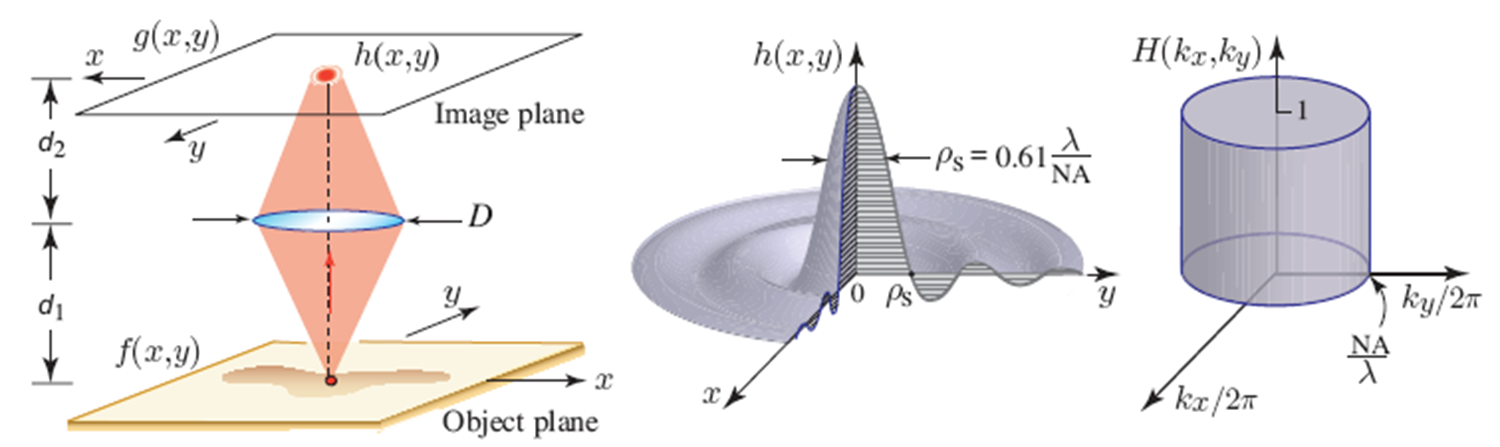

**ILL. 1.6. ***PSF and optical transfer function for diffraction-limited coherent light*


$$\textrm{Width}\;\textrm{of}\;\textrm{PSF}=\rho_s =0\ldotp 61\frac{\lambda }{\textrm{NA}}$$
         
$$\textrm{Bandwidth}=\frac{\textrm{NA}}{\lambda }$$


***Example 1.3***

Circular aperture coherent PSF

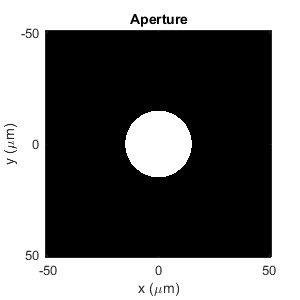

%% Circle Aperture
% without specification, the unit is mm
n=1024; % total number of pixels
x=linspace(-51.2,51.2,n); % the aperture plane
y=linspace(-51.2,51.2,n);
dx = x(2)-x(1);

f = 35;% unit mm
lambda = 1.5;% um wavelength
rd = 15; % radius of the aperture unit mm

[X,Y]=ndgrid(x,y); 
Aperture=zeros(n);
Aperture(X.^2+Y.^2<=(rd)^2)=1; % circular aperture
figure()
imagesc(x,y,Aperture)
colormap('gray')
axis image
title('Aperture'); xlabel('x (\mum)'); ylabel('y (\mum)')
set(gcf,'Position', [100 100 300 300])

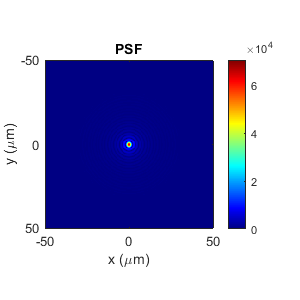

%% the point spread function in the right scale
dkx=2*pi/n/dx;%spatial frequency
dxp=lambda*f/2/pi*dkx; %unit is in um, image space resolution

xp=(-n/2:(n/2-1))*dxp; % the image plane coordinates
yp=(-n/2:(n/2-1))*dxp;

% point spread function:
Psf = fftshift(fft2(fftshift(Aperture)));
Psf_inc = abs(Psf).^2;

figure()
imagesc(xp,yp,abs(Psf))
axis image
colormap('jet')
colorbar
title('PSF')
xlabel('x (\mum)')
ylabel('y (\mum)')
xlim([-50 50])
ylim([-50 50])
set(gcf,'Position', [100 100 300 300])

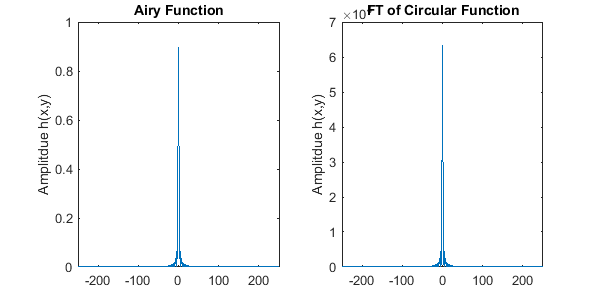

%% compare airy function with fourier transform of the circular function
figure()
% airy function
na = rd/f; % numerical aperture
rho_a=lambda/2/na;
rho=xp./rho_a; % the radial coordinate
h=2*besselj(1,pi.*rho)./(pi.*rho);
subplot(121)
plot(xp,abs(h))
title('Airy Function')
ylabel('Amplitdue h(x,y)')
xlim([-250 250])
%fourier transform of circular function
subplot(122)
plot(xp,abs(Psf(end/2,:)))
title('FT of Circular Function')
xlim([-250 250])
xlabel('')
ylabel('Amplitdue h(x,y)')
set(gcf,'Position', [100 100 600 300])

**1.3.2 Optical spatial filtering**

An ideal 4f system performs a double Fourier transform, which is equivalent to an inverted image, as expected from ray optics.

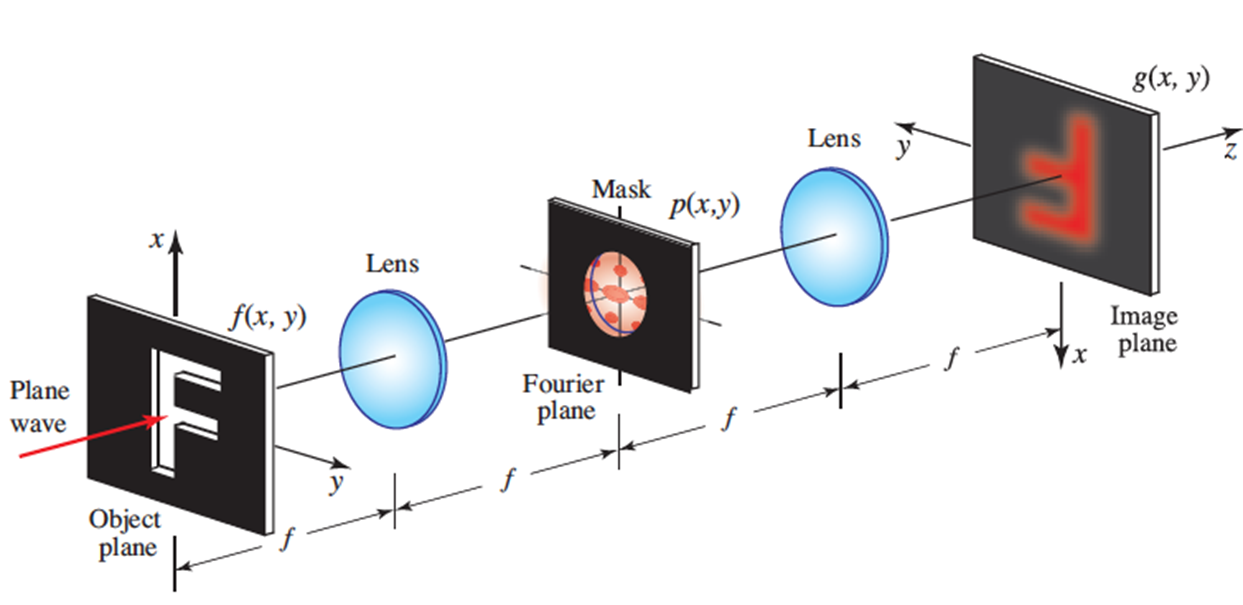

**ILL. 1.7 ***Optical low-pass filtering 4f system*

The front lens performs a Fourier transform from the Object plane to the Fourier plane. A mask, serving as a frequency domain filter, filters out certain frequency components. The back lens performs another Fourier transform, forming a filtered inverted image at the Image plane.

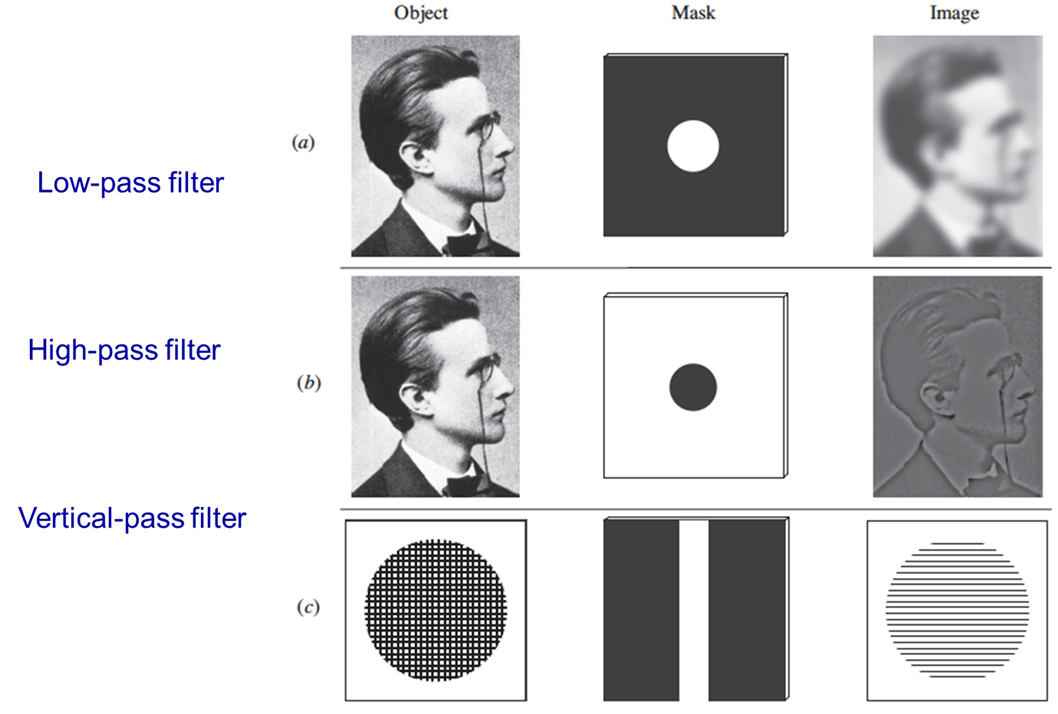

**ILL. 1.8. ***Optical spatial filtering*

## 2. Diffraction-limited incoherent imaging

### 2.1 Incoherence and intensity superposition

Under coherent illumination, the optical fields at the input and output planes are related by the linear relation:


$$E_o \left(x,y\right)=h\left(x,y\right)\otimes E_i \left(x,y\right)$$



$$h=\textrm{coherent}\;\textrm{PSF}$$


Under incoherent illumination, the optical intensities at the input and output planes are related by the linear relation:


$$I_o \left(x,y\right)=h_{\textrm{inc}} \left(x,y\right)\otimes I_i \left(x,y\right)$$



$$I_o =\textrm{image}\;\textrm{intensity},{\;h}_{\textrm{inc}} =\textrm{incoherent}\;\textrm{PSF},\;I_i =\textrm{object}\;\textrm{intensity}$$



$$h_{\mathrm{inc}} \left(x,y\right)={\left|h\left(x,y\right)\right|}^2$$


For coherent light, the principle of superposition applies to the optical field


$$E=h_1 E_1 +h_2 E_2$$


For inchorent light, the field is random with zero average, but has a finite intensity


$${\left|E\right|}^2 ={\left|h_1 E_1 +h_2 E_2 \right|}^2$$



$$={\left|h_1 \right|}^2 {\left|E_1 \right|}^2 +{\left|h_2 \right|}^2 {\left|E_2 \right|}^2 +h_1^* h_2 E_1^* E_2 +h_1 h_2^* E_1 E_2^*$$


wherein the interference terms have zero averages, i.e. $\left\langle E_1 ,E_2^* \right\rangle =0$ and $\left\langle E_1^* E_2 \right\rangle =0$.

Therefore,


$$I={\left|h_1 \right|}^2 I_1 +{\left|h_2 \right|}^2 I_2$$


Therefore, the principle of superposition applies to the intensity and the superoposition of the weights (the PSF) are squared.

### 2.2 PSF of incoherent imaging system

#### 2.2.1 Incoherent PSF and OTF of lens with circular aperture

The incoherent PSF is the square of a coherent PSF.

$h\left(x,y\right)\propto{\left|\frac{2J_1 \left(\pi \rho /\rho_a \right)}{\pi \rho /\rho_a }\right|}^2$, $\rho_s =1\ldotp 22\rho_a$, $\rho_s =1\ldotp 22\lambda \frac{d_2 }{D}$

The incoherent OTF is the autocorellation of the coherent OTF.

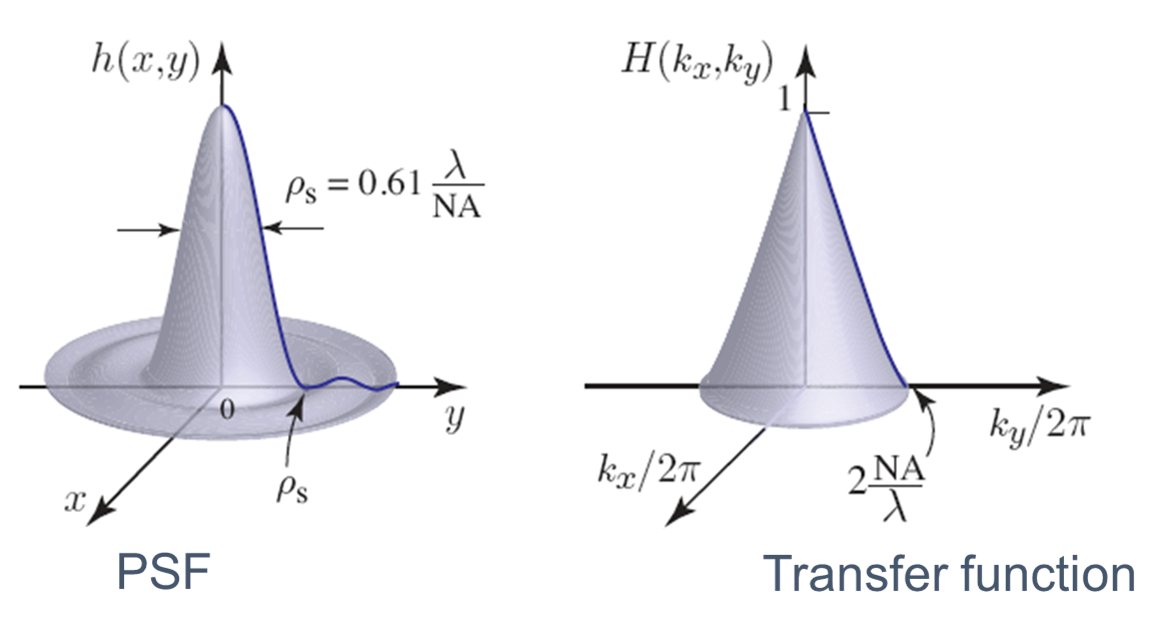

**ILL. 2.1 ***Diffraction-limited incoherent PSF and OTF*

#### 2.2.2 Rayleigh criterion and optical resolution

The criterion states that two point sources of light can be resolved if the first minimum of the diffraction pattern of one source falls on the peak of the diffraction pattern of the other source. Mathematically, this can be expressed as:


$$\rho_s =0\ldotp 61\frac{\lambda }{\textrm{NA}}$$


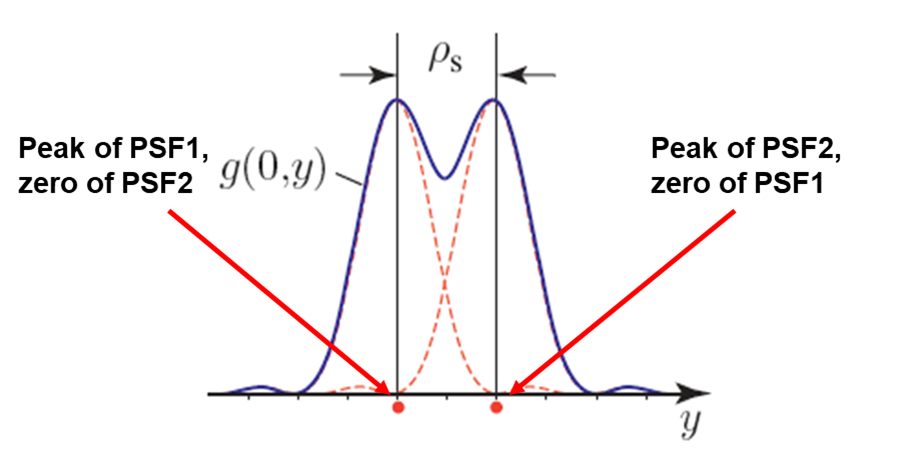

**ILL. 2.2 ***Optical resolution of two point sources*

***Example 2.1***

Incoherent PSF and optical resolution.

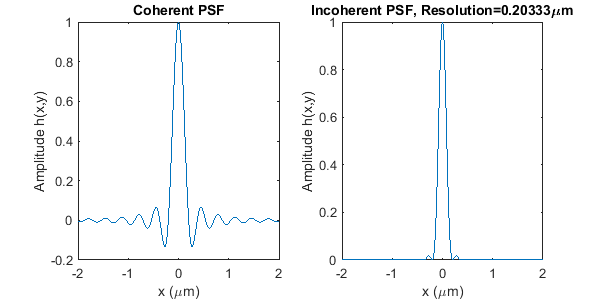

lambda = 0.5;% unit um
NA = 1.5;
rho_a = lambda/2/NA; 
rho_s = 1.22*rho_a; % resolution

rho=linspace(-2,2,1024);
h=2*besselj(1,pi.*rho./rho_a)./(pi.*rho./rho_a);
h_inc=h.^2;% incoherent PSF

figure(); % coherent PSF contrast with incoherent PSF
subplot(121)
plot(rho,h)
title('Coherent PSF')
xlabel('x (\mum)')
ylabel('Amplitude h(x,y)')
subplot(122)
plot(rho,h_inc)
title(['Incoherent PSF, Resolution=',num2str(rho_s),'\mum'])
xlabel('x (\mum)')
ylabel('Amplitude h(x,y)')
set(gcf,'Position', [100 100 600 300])

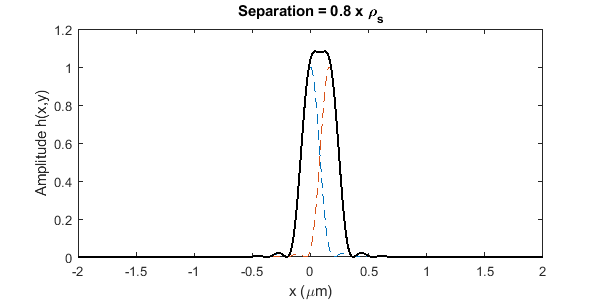

%% Rayleigh criterion
a = 0.8; 
d = a*rho_s;% introducing the separation.
h_inc_sft=(2*besselj(1,pi.*(rho-d)./rho_a)./(pi.*(rho-d)./rho_a)).^2;
h_inc_2p = h_inc+h_inc_sft;% two point superposition

figure();
plot(rho,h_inc, '--', rho, h_inc_sft, '--')
hold on
plot(rho, h_inc_2p, 'k', 'linewidth', 1.5) 
title(['Separation = ',num2str(a),' x \rho_s'])
hold off
xlabel('x (\mum)')
ylabel('Amplitude h(x,y)')
set(gcf,'Position', [100 100 600 300])

### 2.3 Defocused incoherent PSF

When the effects of diffraction are small compared to defocus aberration, geometric optics, as demonstrated in Lecture 4, is a beneficial method to calculate the defocused PSF. 

As the effects of diffraction become more prominent than defocus aberration, geometric optics is no longer a reasonable approach because it does not take the diffraction into account.

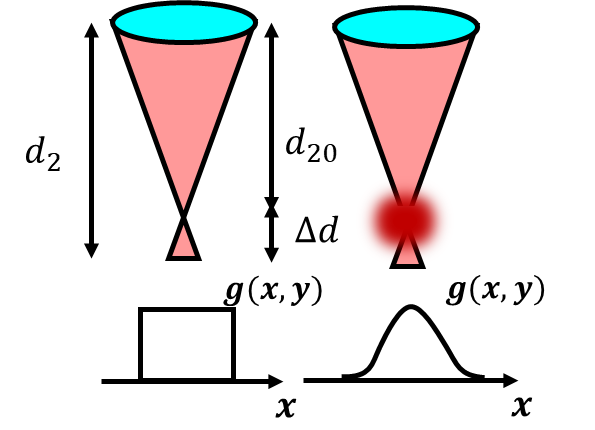

**ILL. 2.3 ***Comparison of defocusing and geometric optics PSFs*

***Example 2.2***

Comparison of geometrical defocused PSF and defocused incoherent PSF (1D)

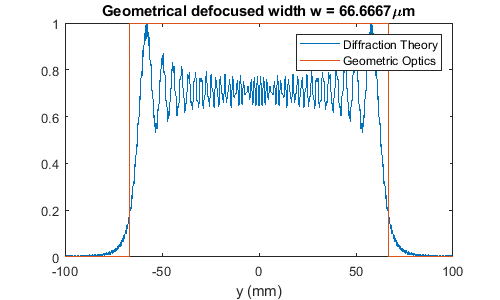

% object is at infinity i.e. 1/d1=0
f = 3; % positive lens unit cm
aper = 1; % half diameter of the aperture
na = aper/f;
del_d =0.02; % unit in cm

%% Geometric point defocusing
d2 = f+del_d;
inv_de = 1/f -1/d2; 
w = inv_de*d2*aper*1e4; % defocus width, unit in um.

% Diffraction defocusing 
lambda = 0.532; %532 nm wavelength unit in micrometer
rho_a=lambda./(2*na);
ly = 100;% area is 200 um in size
ny = 1024;
rho=linspace(-ly,ly,1024);
h=2*sinc(rho./rho_a);% coherent slit PSF at focus

% 1D (slit) defocusing propagates
k=2*pi/lambda;
ky=2*pi/(rho(end)-rho(1))*((-ny/2):(ny/2-1));
H=fftshift(fft(fftshift(h)));
z=del_d*1e4; % propagation distance matches defocusing
Hz=H.*exp(1i.*k*(1-1/2*(ky/k).^2).*z);
hz=fftshift(ifft(fftshift(Hz)));
hz_inc=abs(hz).^2;% intensity
hz_inc_norm = hz_inc./max(hz_inc);

% display
figure();
set(gcf,'Position', [100 100 500 300])
plot(rho,hz_inc_norm)
xlabel('y (mm)')
title(['Geometrical defocused width w = ',num2str(w), '\mum'])
hold on

rect=rectpuls(rho,w*2);
plot(rho,rect);

legend(["Diffraction Theory","Geometric Optics"])